# Obliczanie całek

Aby mieć dokładne wyniki włączamy pokazywanie większej niż zwykle liczby cyfr znaczących.

format long

Definiujemy funkcję Gaussa [funkcję Gaussa](https://pl.wikipedia.org/wiki/Rozk%C5%82ad_normalny) - tu jest wzór napisany w LaTeX, czyli ilustracja nie coś co naprawdę się liczy


$$f(x, x_0, \sigma) =
\frac 1 {\sqrt {2 \pi} \sigma}
 \exp \bigg[ -\frac {(x-x_0)^2} {2 \sigma^2} \bigg]$$


gauss = @(x, x0, sigma) 1 / sqrt(2*pi) ./ sigma .* exp(- (x-x0).^2 / 2 ./ sigma.^2);

Interesuje nas pole powierzchni pod krzywą Gaussa w zakresie od -1 do +1, ogólniej od jakiegoś a do jakiegoś b. Zdefiniujemy też N jako liczbę punktów potrzebnych do wykresu i utworzymy x jako wektor wartości zmiennej niezależnej.

a = -1;  % dolna granica całkowania
b = +1;  % górna granica całkowania
N = 500; % liczba punktów - w zasadzie tylko do wykresów
x = linspace(a, b, N);

Obliczenia chcemy przeprowadzić dla różnych wartości parametru $\sigma$.

sigma_values = [1/3; 1/2; 1; 2; 3]

sigma_values =    0.333333333333333
   0.500000000000000
   1.000000000000000
   2.000000000000000
   3.000000000000000


Zobaczmy wykresy - zrobimy je na jednym rysunku - nie musimy nawet do tego używać pętli for - zadziała magia obliczeń na wektorach i macierzach jaka jest w Matlabie.

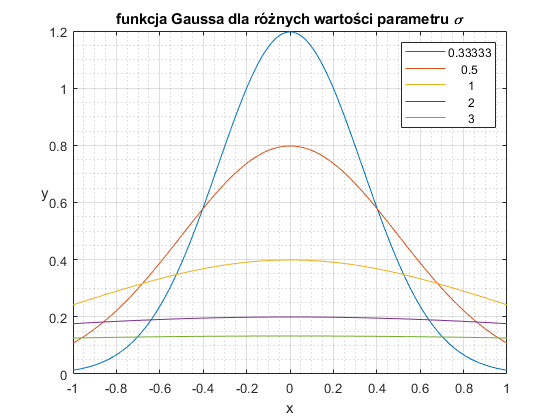

figure(1); 
clf; % clf nie zaszkodzi

y = gauss(x, 0, sigma_values);
plot(x, y);

grid minor;
grid on;
title('funkcja Gaussa dla różnych wartości parametru \sigma');
xlabel('x');
ylabel('y', 'rotation', 0); % rotation=0 ustawia linię tekstu równolegle do osi x
legend(num2str(sigma_values)); % num2str przekształca wektor wartości na tablicę napisów
hold all;

integral_values = arrayfun(@(sigma) integral(@(x) gauss(x, 0, sigma), a, b), sigma_values)

integral_values =    0.997300203936740
   0.954499736103642
   0.682689492137086
   0.382924922548026
   0.261117319636473


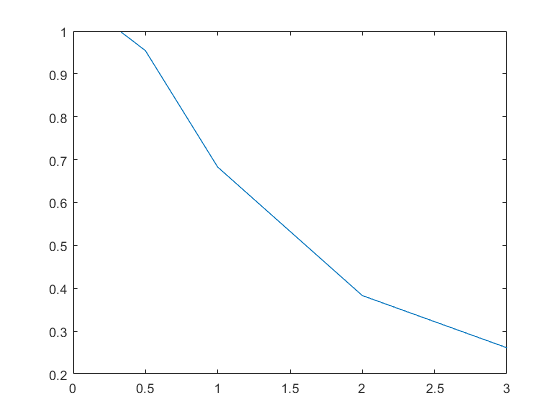

figure(2);
plot(sigma_values, integral_values)